# **HW #5 - Genetic Algorithm Crossover Comparison**

### Problem Statement:

Use a genetic algorithm to find the global optimum of the following objective function:


$$f(x,y)=\exp\left( \frac{-\left[ (x-3)^2+(y-3)^2\right]}{5} \right) +
\exp\left( \frac{-\left[ x^2+(y+3)^2\right]}{5} \right) + 
0.2\left[ \cos\left(\frac{x\pi}{2}\right) + \cos\left(\frac{y\pi}{2}\right)\right] +
5$$


objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;

Mathematically we know this function has a maximum height of 1.6903 in the range of -5 to 5 for x and y.

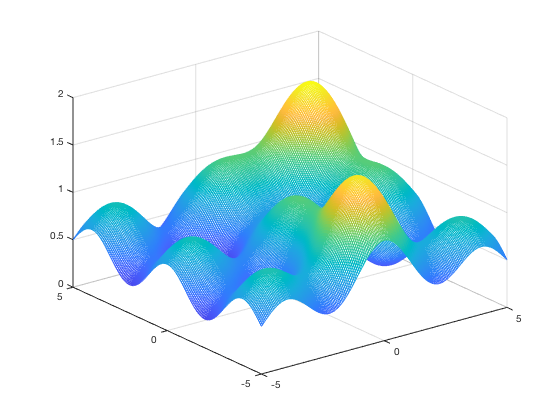

[x,y]=meshgrid(-5:0.05:5);
mesh(x,y,objf(x,y));

### Methods:

- Representation: Binary

- Selection: Elitist, Rank Selection

- Mating/Variation: Single Point Binary Crossover, Uniform Crossover

### Initialize Parameters

For a genetic algorithm, the important parameters are population size, number of generations to execute, fraction of population seleected for mating, the data representation, and the range of data.

clc;
clear;
    % ***** User Changable Variables ***** %
objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;

pop = 40;               %population size
gen = 200;              %number of generations
pcntsel = 0.5;          %fraction of candidated selected for next generation

precision = 8;          %precision of real number represenation (ex. 8 -> 8-bit represenation)
range = [-5 5; -5 5];   %bounds for input variables

% ***** Calculations ***** %
mu = round(pcntsel*pop);    %number of parents selected
lambda = pop - mu;          %number of new candidates in each generation (children)

### Generate Initial Population

Generally, the initial population is generated randomly within specified ranges. 

for iteration = 1:2

### Genetic Algorithm

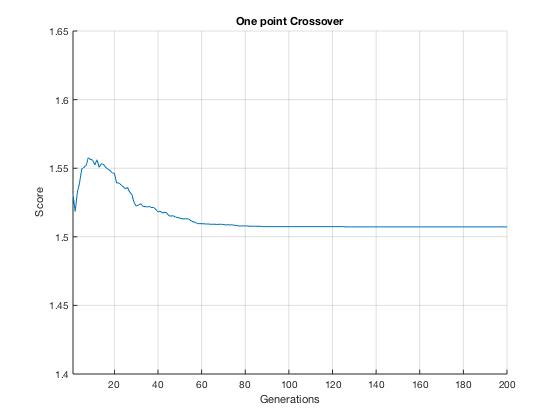

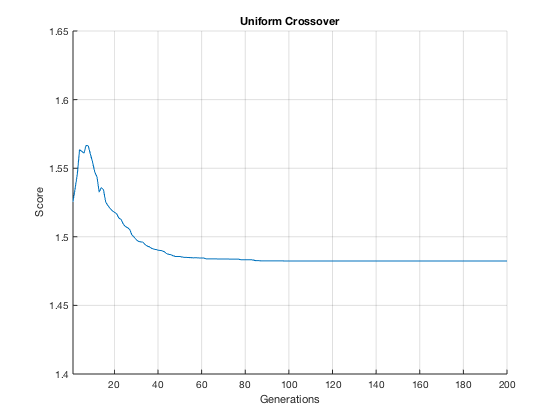

    array = zeros(gen,1);
    for t = 1:gen
        candidate.binx = rand(pop,precision)>0.5;   %generate binary representation
        candidate.biny = rand(pop,precision)>0.5;
        
        bestGenArray = zeros(200,1);
        
        for i = 1:gen
    
        % ********* Convert Representation ****** %
            candidate.x = (range(1,1)-range(1,2))*(bi2de(candidate.binx)/(2^precision-1))+range(1,2);
            candidate.y = (range(2,1)-range(2,2))*(bi2de(candidate.biny)/(2^precision-1))+range(2,2);
        % *************************************** %
    
        % ********* Get Fitness ***************** %
            candidate.fit = objf(candidate.x,candidate.y);
        % *************************************** %
    
        % ********* Selection ******************* %
            %Linear (Roulette Wheel) Selection
            fitsum = sum(candidate.fit);
            [cfit, I]= sort(candidate.fit);
            
            
            %top pick 
            bestGenArray(i) = candidate.fit(I(pop,:),:);
            
            candidate.p = cfit./fitsum;
            [m,n] = size(candidate.p);
            candidate.sp = cumsum(candidate.p);
            
          
        
          
          %Selection
            for j = 1:mu
                sel=rand;
                for k = 1:pop
                    if candidate.sp(k) >= sel
                        newCandidate.binx(j,:) = candidate.binx(I(k),:);
                        newCandidate.biny(j,:) = candidate.biny(I(k),:);
                    break;
                    end
                end
            end
    
   
   
        % *************************************** %
    
        % ********* Create Offspring ************ %
            
        if iteration == 1
            [newCandidate] = opoint_crossover(newCandidate, mu, precision, lambda);
            T = ('One point Crossover');
        else
            [newCandidate] = u_crossover(newCandidate, mu, precision, lambda);
            T = ('Uniform Crossover');

        end
        % *************************************** %
    
        % ********* Next Generation ************* %
            candidate = newCandidate;
        % *************************************** %
        end
        array = array + bestGenArray;

    end
    array = array./t;

    a_axis = 1:200;

    figure();
    title(T);
    hold on;
    axis([1 200 1.4 1.65]);
    b = array(a_axis);
    plot(a_axis,b);
    xlabel('Generations')
    ylabel('Score')
    grid on;
    hold off;

end



function [n_generation] = opoint_crossover(n_generation, mu, precision, lambda)
    % Ttile: Onepoint  crossover algorithm implementation


% input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation

   
    %i = 1;
    %while i <= lambda
    for i=1:lambda
        
        ParentIndex1 = 0;
        ParentIndex2 = 0;
        
        % cross point
        crosspoint1 = randi([1 precision], 1, 1); 
        crosspoint2 = randi([1 precision], 1, 1);
        
        
     
        %random parent  selection   
        if ParentIndex1 == ParentIndex2 
            ParentIndex1 = randi([1 mu], 1, 1);
            ParentIndex2 = randi([1 mu], 1, 1);
        end
        
        % first parent 
        Parent1x = n_generation.binx(ParentIndex1,:);
        Parent1y = n_generation.biny(ParentIndex1,:);
        % second parent 
        Parent2x = n_generation.binx(ParentIndex2,:);
        Parent2y = n_generation.biny(ParentIndex2,:);
        
        
        % next generation 
        n_generation.binx(mu+i,:) = [Parent1x(1:crosspoint1),Parent2x(crosspoint1+1:precision)];
        n_generation.biny(mu+i,:) = [Parent1y(1:crosspoint2),Parent2y(crosspoint2+1:precision)];
        
        n_generation.binx(mu+i,:) = [Parent2x(1:crosspoint1),Parent1x(crosspoint1+1:precision)];
        n_generation.biny(mu+i,:) = [Parent2y(1:crosspoint2),Parent1y(crosspoint2+1:precision)]; 
        
    
        
        
    end
        

end




function [n_generation] = u_crossover(n_generation, mu, precision, lambda)
% Ttile: Uniform crossover algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation
        
        % initialization 

        ch1x = zeros(1,precision);
        ch2x = zeros(1,precision);
        ch1y = zeros(1,precision);
        ch2y = zeros(1,precision);
        
       
    for i=1:lambda
        
        %Mask generation 
        mask = randi([0 1], 1, precision); 
        
        % Parents selection 
        p_index1 = 0;
        p_index2 = 0;
        
        %pick up the parent in random
        while p_index1 == p_index2
            p_index1 = randi([1 mu], 1, 1);
            p_index2 = randi([1 mu], 1, 1);
        end
        
        % first parent
        p_1x = n_generation.binx(p_index1,:);
        p_1y = n_generation.biny(p_index1,:);
        % second parent 
        p_2x = n_generation.binx(p_index2,:);
        p_2y = n_generation.biny(p_index2,:);
        
       % child creation 
        for j = 1 : precision
            if mask (j) == 1
                ch1x(j) = p_1x(j);
                ch1y(j) = p_1y(j);
                ch2x(j) = p_2x(j);
                ch2y(j) = p_2y(j); 
            else
                ch1x(j) = p_2x(j);
                ch1y(j) = p_2y(j);
                ch2x(j) = p_1x(j);
                ch2y(j) = p_1y(j); 
            end
        
        
        end
        % next generation 
        n_generation.binx(mu+i,:) = ch1x(1,:);
        n_generation.biny(mu+i,:) = ch1y(1,:);
        n_generation.binx(mu+i,:) = ch2x(1,:);
        n_generation.biny(mu+i,:) = ch2y(1,:);
    end
        
   

end



Discussion:  

Genetic algorithms (GA) are used to to solve combinatorial optimization problems. One of the problems in using genetic algorithms is the choice of crossover operator. The GA is applied to the optimization problem. 

The initial populations are generated randomly. The quality of this population is poor and one way to improve it is to incorporate some chromosomes generated by priority rules.

The genetic algorithms typically use the following types of operators: Selection: Operator for selecting individuals for reproduction according to their fitness:

    Crossover (Sexual Recombination): Operator of merging the genetic information of two individuals. In many respects the effectiveness of crossover is depended on coding.

    Mutation (Asexual): In real evolution, the genetic material can by changed randomly by erroneous reproduction or other deformations of genes, e.g. by gamma radiation. In genetic algorithms, mutation realized as a random deformation of alleles with a certain probability. 

After reproduction, crossover may proceed in two steps. First, members of the newly reproduced chromosomes in the mating pool are mated at random. Second, each pair of chromosomes undergoes crossover as follows: an integer position k along the chromosome is selected uniformly at random between 1 and the chromosome length l. Two new chromosomes are created swapping all the genes between k+1 and l.

In uniform crossover, a value of the first parent’s gene is assigned to the first offspring and the value of the second parent’s gene is to the second offspring with a probability value.

High fluctions of one point crossover can be seen in figure. On the other hand, the uniform crossover figure shows more smoothness than one point crossover. 

Finally, we can conclude that the uniform cross over algorithm has higher efficiency.